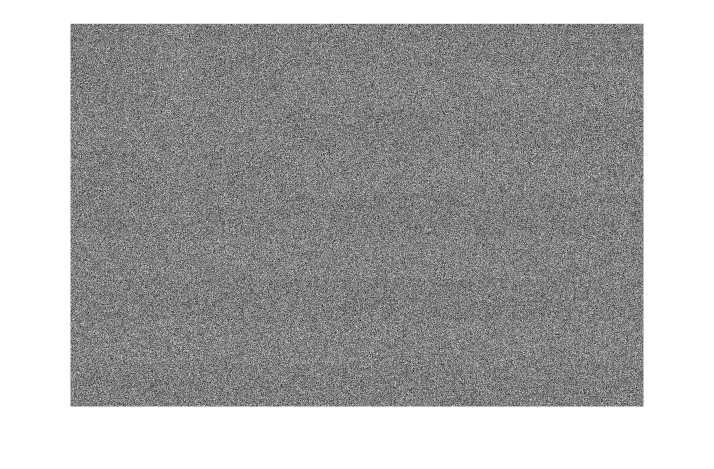

%% Laad foto in en toon deze.
img = double(imread('Geheim.png'))/255;
% img = rgb2gray(img_color); % Zet om in zwart-wit.
imshow(img)

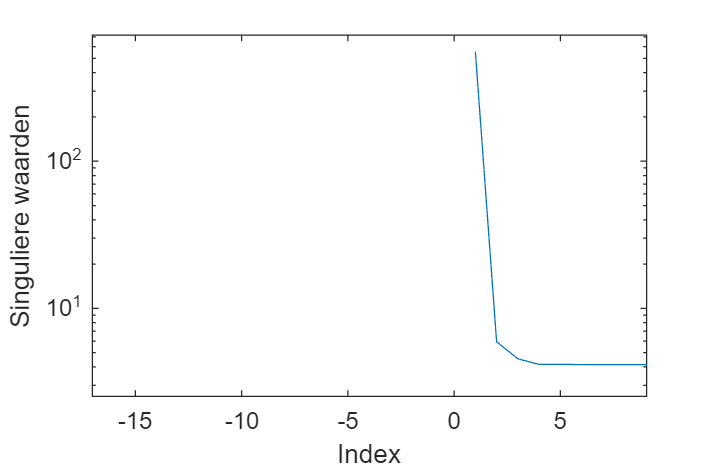

%% Bereken de singulierewaardenontbinding.
[U, S, V] = svd(img);

% Toon singuliere waarden.
singuliere_waarden = diag(S);
semilogy(singuliere_waarden)
xlabel('Index')
ylabel('Singuliere waarden')

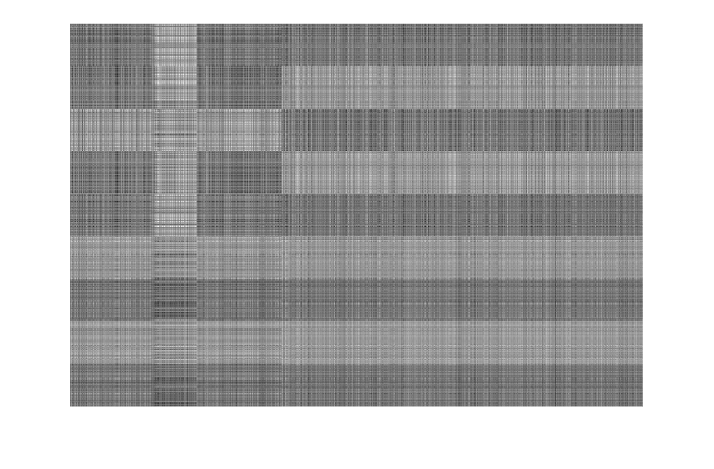

%% Kies compressie en bekijk resultaten.
R = 3; % Selecteer benaderingsrang.

% Voer compressie uit.
Uc = U(:, 1:R);
Sc = S(1:R, 1:R);
Vc = V(:, 1:R);
img_compressed = Uc * Sc * Vc';
img_compressed = rescale(img_compressed);

% Toon gecomprimeerd beeld.
imshow(img_compressed)


% Bereken compressiefactor.
compressiefactor = numel(img) / (numel(Uc) + numel(Sc) + numel(Vc));
fprintf('Het beeld is %2.2f keer kleiner', compressiefactor);

Het beeld is 179.76 keer kleiner